# Project Overview: Optimizing Biomechanical Polynomial Models for Muscle Tissue Stress-Strain Relationships

## Importance of the Project

Understanding the mechanical properties of human muscle tissue is crucial in various fields such as biomechanics, surgical simulation, and rehabilitation engineering. The compressive properties, particularly in the transverse direction to the muscle fiber, play a significant role in these applications. By accurately modeling the stress-strain relationship, researchers can better predict tissue behavior under different loading conditions, aiding in the development of safer surgical procedures, more effective rehabilitation protocols, and improved biomechanical designs.

## Project Objectives

The primary objective of this project is to optimize polynomial models to characterize the stress-strain relationships in human muscle tissue. By fitting regression curves to experimental data obtained from compression tests, the project aims to identify the most suitable polynomial order and fitting method for accurately capturing the nonlinear behavior of muscle tissue under loading.

## Computational Methods

The project utilizes MATLAB for data analysis and modeling. Various computational methods are employed, including least-squares fitting, absolute error minimization, and optimization algorithms such as `fminsearch`. These methods allow for the estimation of polynomial coefficients that best represent the observed stress-strain data.

## Tasks and Goals

The project is divided into several tasks, each addressing specific aspects of the modeling process. These tasks include data visualization, model fitting, error analysis, and comparison of different fitting approaches. The ultimate goal is to identify the optimal polynomial model that minimizes errors and accurately represents the complex stress-strain relationship in muscle tissue.

## Expected Outcomes

Upon completion of the project, we expect to have a refined understanding of the stress-strain behavior of muscle tissue and an optimized polynomial model for predicting tissue response under various loading conditions. The project outcomes will contribute to advancements in biomechanics research, surgical simulation techniques, and rehabilitation engineering practices, ultimately leading to improved patient outcomes and enhanced medical technologies.

close all
clear

The compressive properties of human muscle tissue play a significant role in impact biomechanics, surgical simulation, and rehabilitation engineering. The primary loading direction, crucial for these applications, is transverse to the muscle fiber direction. Tests conducted at TCD on pig muscle samples using a universal testing machine revealed nonlinear anisotropic behavior under quasi-static loading conditions [1]. In this assignment, regression curves will be fitted to data from a compression test on a sample conducted in the transverse direction, denoted as cross-fiber (XF) or corresponding to the blue curve in the figure below. It will be evident that the relationship between stress and strain is not linear. Therefore, defining a constant value for the slope of the stress-strain curve (i.e., assuming a Young’s Modulus) will not yield a very good fit to the data.

The data is stored in a file muscle_data_2023.xls. The following Matlab code reads in the data.

raw_data = xlsread('muscle_data_2023.xlsx');
strain = raw_data(:,3);      %yk
stress = raw_data(:,4);      %φk


I will now investigate two different models for the data. We will utilize the model formulation \( \hat{y}_k = f(\phi_k) \), where \( \hat{y}_k \) represents our estimated stress given the measured strain \( \phi_k \) for the kth measurement. The error between the observed stress \( y_k \) and the modeled (estimated) stress \( \hat{y}_k \) is denoted as \( e_k = y_k - \hat{y}_k \).

# TASK 1

I will plot the observed stress (\( y_k \)) against strain (\( \phi_k \)) in Figure 1, using a blue line with a thickness of 3.

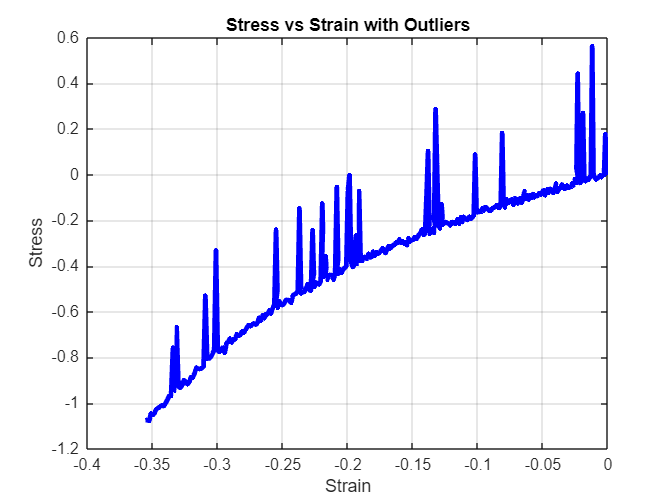

% Plot the data with a blue line of thickness 3
figure(1);
plot(strain, stress, 'b-', 'LineWidth', 3);

% Add labels and title
xlabel('Strain');
ylabel('Stress');
title('Stress vs Strain with Outliers');

% Display the plot
grid on

Note that the stress data is corrupted by erroneous measurements (outliers).

# TASK 2

I will fit the data to a polynomial model using a least-squares (LS) fit. To estimate the best or appropriate model order \( m \), I will test 5 model orders, represented as \( m = [1 : 5] \). For each polynomial model with order \( m \), I will use the `polyfit` function in Matlab to estimate the coefficients of the polynomial fit to the data. Since `polyfit` uses the LS error criterion for fitting, I will calculate the sum squared error for each polynomial fit and store the resulting data in the vector `sse_per_m`. This vector will have 5 elements, corresponding to the 5 model orders tested.

In Figure 2, I will plot `sse_per_m` versus the model order and use it to select the optimal model order \( \hat{m} \) for this problem. I will use a red line with a thickness of 3 for this plot, and appropriately label the figure and axes. The selected model order will be assigned to the variable `my_m`.

m = [1 : 5];


for i = 1:m(end)
    third_order_coefficients = polyfit(strain, stress, i);


    % Calculate the predicted stress values using the polynomial fit
    third_order_estimated_signal = polyval(third_order_coefficients, strain);
    
    % Calculate the sum squared error
    sse_per_m(i) = sum((stress - third_order_estimated_signal).^2);

end


Now we graph everything

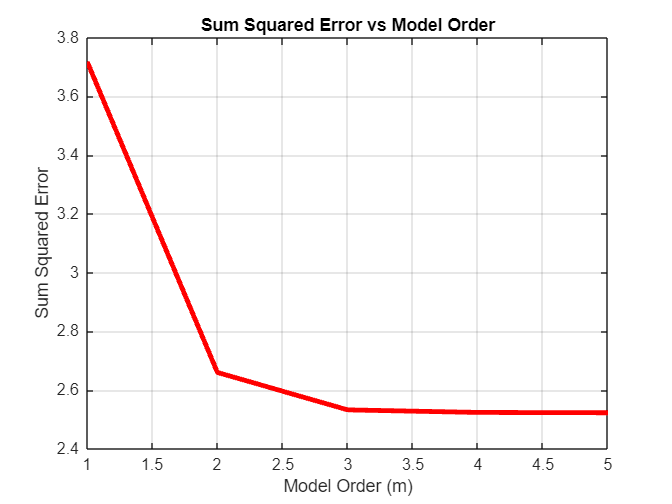

% Plot sum squared error versus model order
figure(2);
plot(m, sse_per_m, 'r-', 'LineWidth', 3);

% Add labels and title
xlabel('Model Order (m)');
ylabel('Sum Squared Error');
title('Sum Squared Error vs Model Order');

% Display the plot
grid on;

% select the model order
my_m = 3;


# TASK 3

With my selected model order \( \hat{m} \), I will calculate the estimated signal \( \hat{y}_k \) and overlay that line in red on the plot in Figure 1. I will assign my estimated signal \( \hat{y}_k \) to the variable `est_stress`.third_order_coefficients = polyfit(strain, stress, my_m);


% Calculate the predicted stress values using the polynomial fit
third_order_estimated_signal= polyval(third_order_coefficients, strain);


Now we graph everything

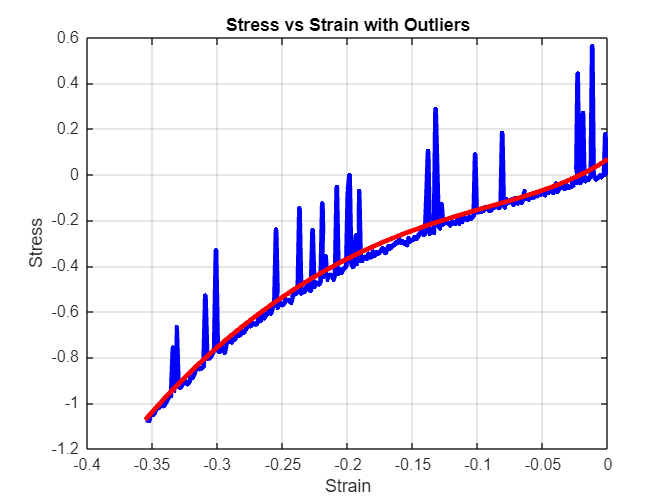

% Plot the data with a blue line of thickness 3
figure(1);
plot(strain, stress, 'b-', 'LineWidth', 3);

% Add labels and title
xlabel('Strain');
ylabel('Stress');
title('Stress vs Strain with Outliers');

% Display the plot
grid on
hold on

% Plot the data with a red line of thickness 3
plot(strain, third_order_estimated_signal, 'r-', 'LineWidth', 3);

hold off

# TASK 4

I will calculate the error between my estimate and the observed stress for the coefficient of determination. Subsequently, I will plot a histogram with 20 bins in Figure 3 to illustrate the distribution of errors, utilizing the `hist` command in Matlab (e.g., `hist(data, 20)`). The resulting plot should resemble the one shown on the side panel (without the need for a title). It's essential to note that the values in this plot may differ from my estimates. Finally, I will compute the coefficient of determination for this polynomial fit and assign it to the variable `ccoef_p`.

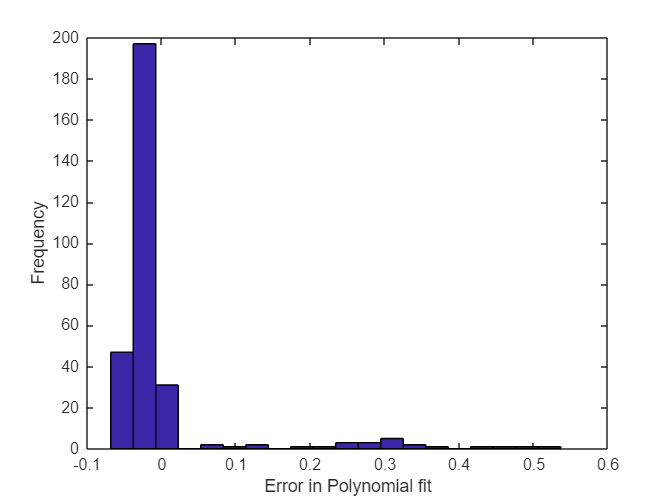

% Calculate the error
error = stress - third_order_estimated_signal;

% Plot histogram of errors in Figure 3
figure(3);
hist(error, 20);
xlabel('Error in Polynomial fit');
ylabel('Frequency');

% Calculate the coefficient of determination (R-squared)

ssr = sum(error.^2);  % sum of squared error

sst = sum((stress - mean(stress)).^2);  % total sum of squares from mean

ccoef_p = 1 - ssr/sst;  % coefficient of determination

# TASK 5

To fit the stress data to a polynomial of order 4, I will use the absolute error as the criterion for the best fit. 

The formulation of the model is \( \hat{y}_k = a_0 + a_1 x_k + a_2 x_k^2 + a_3 x_k^3 + a_4 x_k^4 \), where \( \hat{y}_k \) is the estimated stress given a strain measurement \( \phi_k \). 

The task is to estimate the best set of coefficients \( a_k \) that minimize \( \sum |y_k - \hat{y}_k| \). I will begin with an initial estimate of [0.2, 0.2, 0.2, 0.2, 0.2]. Using these estimated values for \( a_0, a_1, a_2, a_3, a_4 \), I will calculate the estimated signal \( \hat{y}_k \) and superimpose that line in black/dashed on the plot in Figure 1. 

The final Figure 1 should resemble the plot in the side panel.

% Initial estimate for coefficients
initial_coeff = [0.2, 0.2, 0.2, 0.2, 0.2];

% Fit polynomial of order 4 with absolute error minimization
options = optimset('Display', 'on');

fourth_order_coefficients = fminsearch( @(coeff) sum( abs( polyval(coeff, strain) - stress ) ), initial_coeff, options);


This line employs the `fminsearch` function in MATLAB, designed for unconstrained optimization of a function. Specifically, the function being optimized is the sum of absolute differences between the observed stress (`stress`) and the stress predicted by a fourth-order polynomial model (`polyval(coeff, strain)`). The objective is to determine the coefficients (`coeff`) that minimize this sum of absolute differences. To sum up, this line of code finds the coefficients for a fourth-order polynomial model that minimizes the sum of absolute differences between the observed stress and the stress predicted by the model, utilizing the `fminsearch` optimization algorithm.

% Calculate the estimated signal using the fitted coefficients
fourth_order_estimated_signal = polyval(fourth_order_coefficients, strain);


Now we graph everything

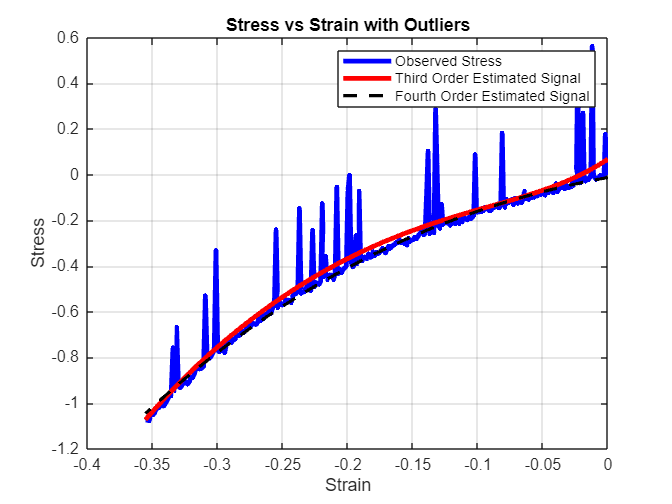

% Plot the data with a blue line of thickness 3
figure(1);

plot(strain, stress, 'b-', 'LineWidth', 3);

% Add labels and title
xlabel('Strain');
ylabel('Stress');
title('Stress vs Strain with Outliers');

% Display the plot
grid on
hold on

% Plot the data with a red line of thickness 3
plot(strain, third_order_estimated_signal, 'r-', 'LineWidth', 3);

% Plot the estimated signal in black/dashed
plot(strain, fourth_order_estimated_signal, 'k--', 'LineWidth', 2);

% Display the legend
legend('Observed Stress', 'Third Order Estimated Signal', 'Fourth Order Estimated Signal');

hold off

# TASK 6

I will calculate the Mean Squared Error (MSE) between my new (robust) estimate and the observed stress but only for samples 25 to 70. The resulting value will be assigned to the variable `mse_nl`. Additionally, I will perform a least-squares (LS) line fit to estimate the coefficients for the model order 4 (previously done in Task 2) and measure the resulting MSE for the same set of samples. This value will be assigned to the variable `mse_ls`. Finally, I will print out these two values to the command line. The objective of this task is to demonstrate that in an area not corrupted by outliers, the MSE using the robust line fit is expected to be better than the MSE using the LS fit.

% Calculate the Mean Squared Error (MSE) for the robust estimate (samples 25:70)
samples_subset = 25:70;

mse_nl = mean((stress(samples_subset) - fourth_order_estimated_signal(samples_subset)).^2);

% Fit polynomial of order 4 using LS for the same set of samples
fourth_order_coefficients_least_squared_fit = polyfit(strain(samples_subset), stress(samples_subset), 4);
fourth_order_estimated_signal_least_squared_fit = polyval(fourth_order_coefficients_least_squared_fit, strain);

% Calculate the MSE for the LS fit
mse_ls = mean((stress(samples_subset) - fourth_order_estimated_signal_least_squared_fit(samples_subset)).^2);


% Print out the MSE values

fprintf('MSE of LS fit = %.4f\n', mse_ls);

MSE of LS fit = 0.0001


fprintf('MSE of Robust fit = %.4f\n', mse_nl);

MSE of Robust fit = 0.0001


# References 

[1] M. Van Loocke, C.G. Lyons, and C.K. Simms. A validated model of passive muscle in compression. Journal of Biomechanics, pages 2999–3009, October 2005.